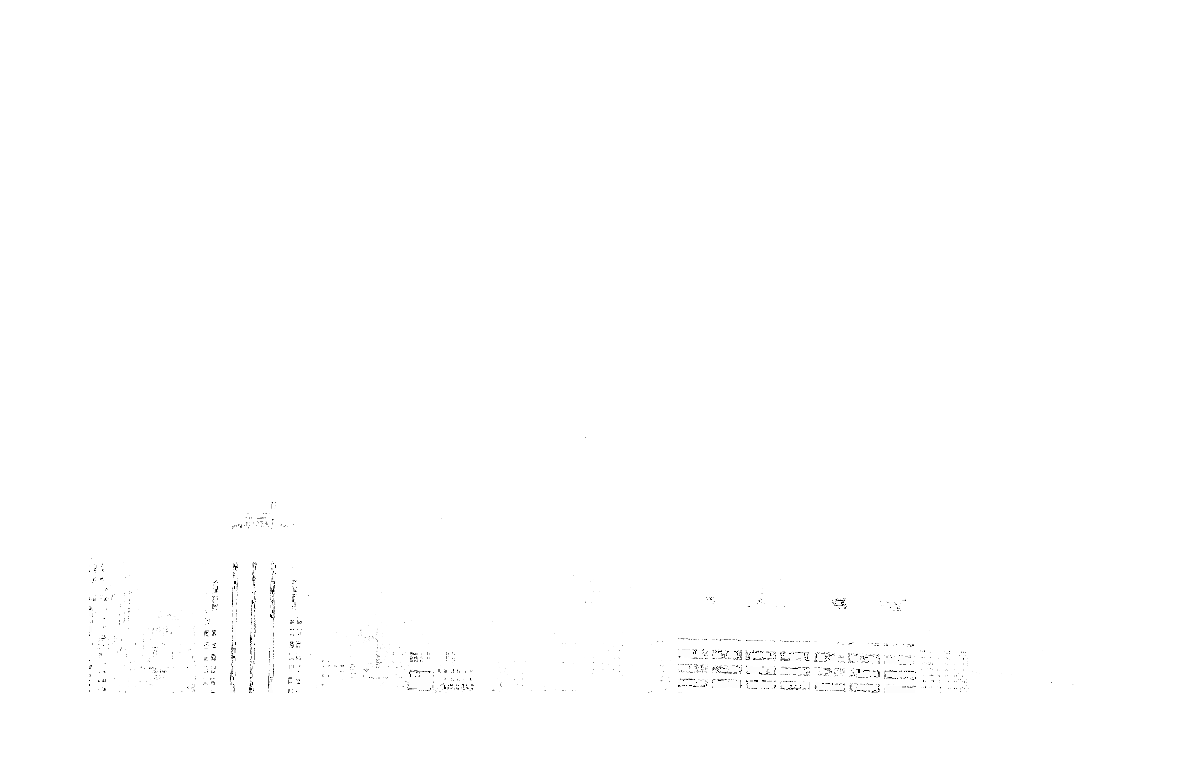

% Part 3: Color to Grayscale
im = double(imread("Week 1\empire.jpg"))/255;
grayImage = 0.2989*im(:,:,1) + 0.5870*im(:,:,2) + 0.1140*im(:,:,3);
imwrite(grayImage, "Week 1\grayImage.jpg");
% Part 4: Binary
thresh_1 = 0.25; thresh_2 = 0.5; thresh_3 = 0.75;
BinaryOne = zeros(size(grayImage));
BinaryOne(grayImage>=thresh_1) = 1;
imwrite(BinaryOne, "Week 1\BinaryOne.jpg");


BinaryTwo = zeros(size(grayImage));
BinaryTwo(grayImage>=thresh_2) = 1;
imwrite(BinaryTwo, "Week 1\BinaryTwo.jpg");

BinaryThree = zeros(size(grayImage));
BinaryThree(grayImage>=thresh_3) = 1;
imwrite(BinaryThree, "Week 1\Binarythree.jpg");

% Part 5 Gamma Correction
Gamma_1 =(im(:,:,1)).^0.2+ (im(:,:,2)).^0.2 + (im(:,:,3)).^0.2;
imwrite(Gamma_1, "Week 1\Lowest_gamma.jpg");
imshow(Gamma_1)

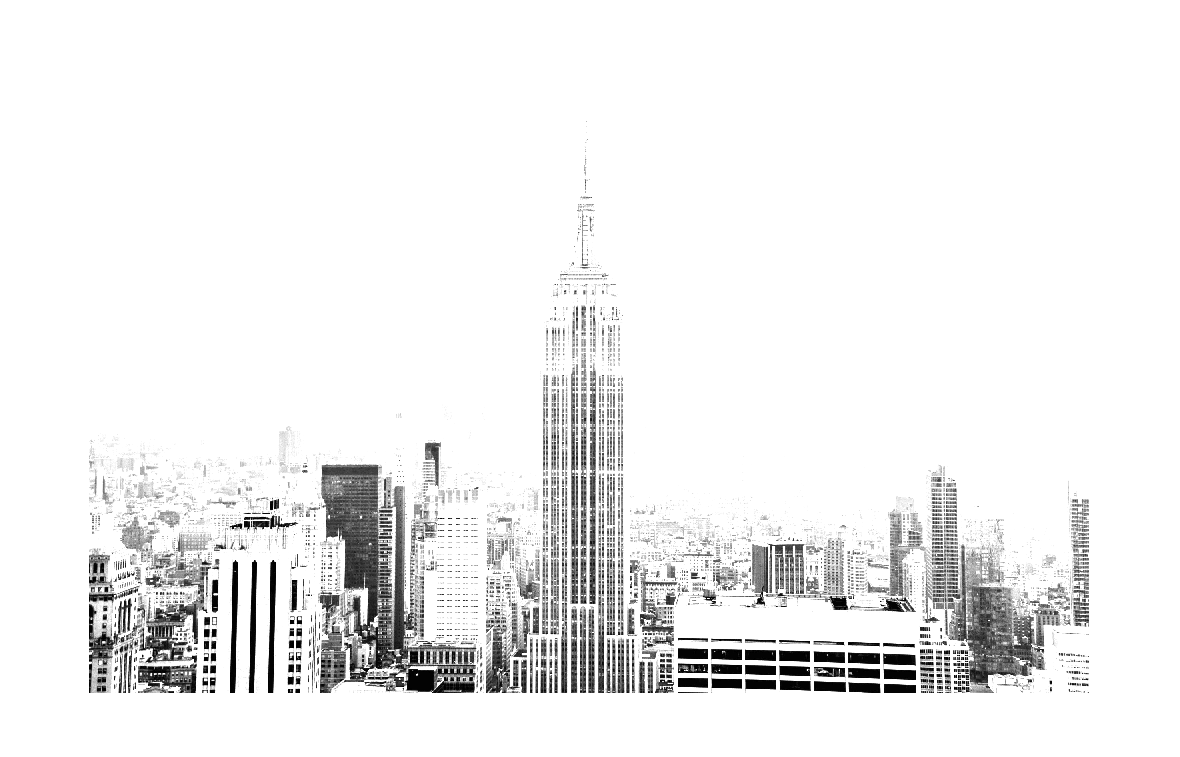


Gamma_2 =(im(:,:,1)).^1+ (im(:,:,2)).^1 + (im(:,:,3)).^1;
imwrite(Gamma_2, "Week 1\middleGamma.jpg");
imshow(Gamma_2)

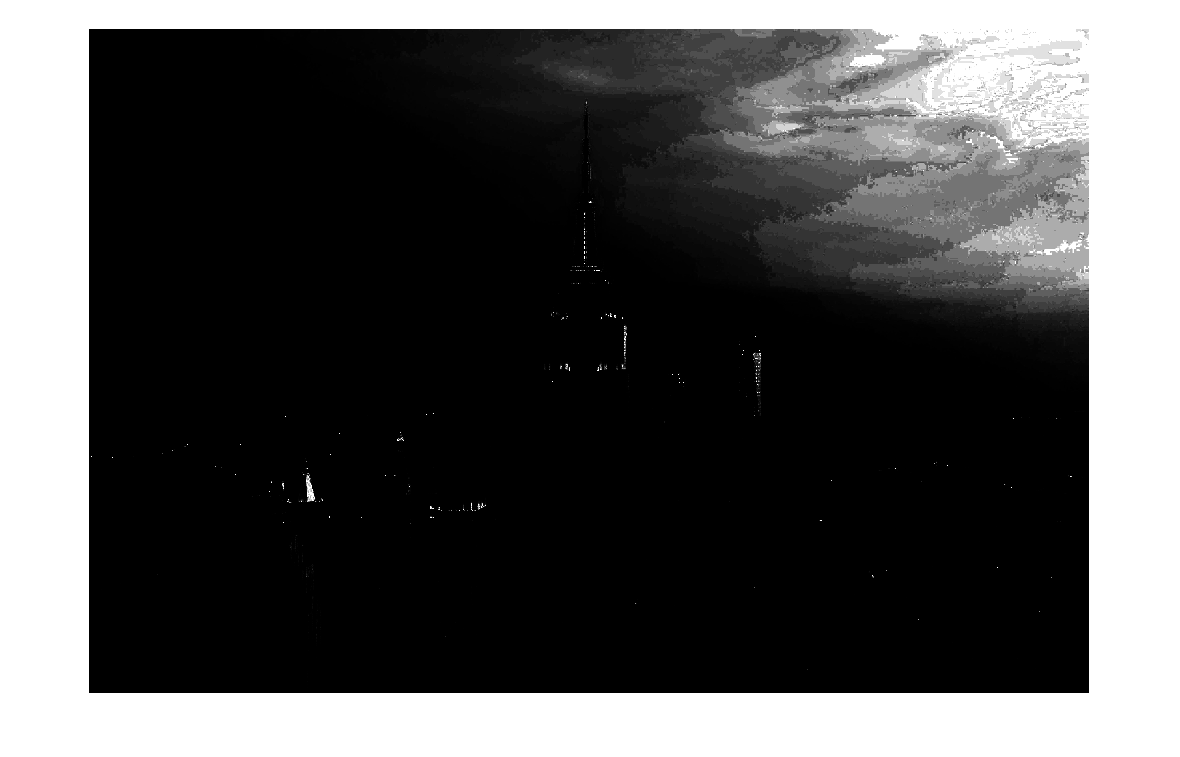


Gamma_3 =(im(:,:,1)).^50+ (im(:,:,2)).^50 + (im(:,:,3)).^50;
imwrite(Gamma_3, "Week 1\highest_gamma.jpg");
imshow(Gamma_3)